# MATLAB for Geoscientists 3 - University of Maryland

These examples demonstrate how to interact with built in MATLAB geoscience reference material and different options for displaying data on map projections. An extended example shows how to access netCDF file sources and extract relevant data to then create an animated figure. 

# Display Moon Albedo

Load moon albedo data and a geographic cells reference object.

load moonalb20c

Then, display the data. To do this, create a map and specify its projection as orthographic. Display the data as a texture map using the `geoshow` function. Then, change the colormap to grayscale and remove the axis lines.

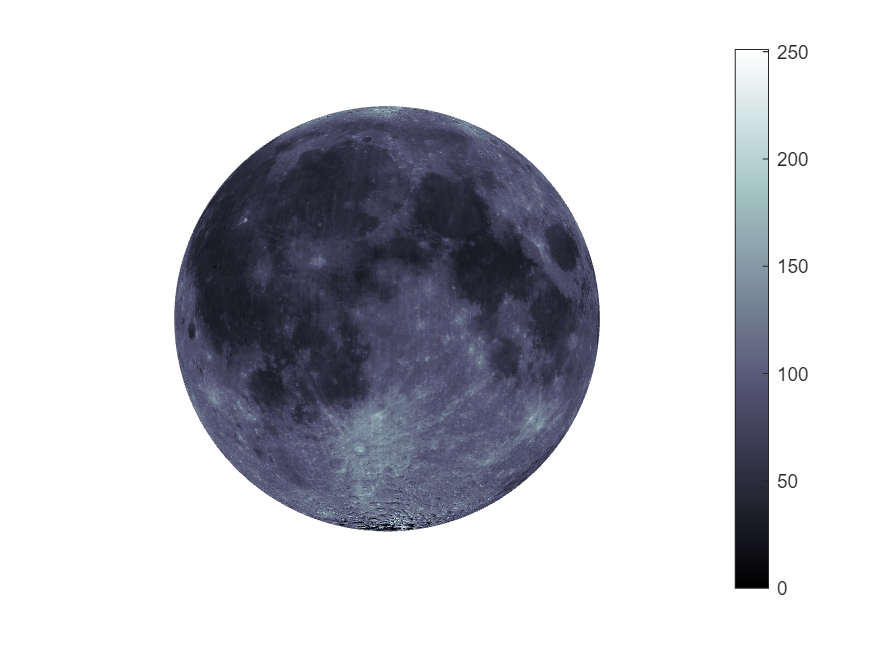

h=figure;
%help referenceEllipsoid
%subplot(1,2,1)
ax1 = axesm('globe','Grid','off', 'MeridianLabel','off','ParallelLabel','off','Geoid',...
    referenceEllipsoid('moon'));
geoshow(moonalb20c,moonalb20cR,'DisplayType','texturemap')


axis off; framem on
colormap(ax1,bone)
colorbar
view([449 -6])



% subplot(1,2,2)
% ax2 = axesm('globe','Grid','off', 'MeridianLabel','off','ParallelLabel','off','Geoid',...
%     referenceEllipsoid('moon'));
% geoshow(moonalb20c,moonalb20cR,'DisplayType','texturemap')
% 
% axis off; framem on
% colormap(ax2,bilbao)
% colorbar
% view([449 -6])

# Show Height of the Geoid

[N,R] = egm96geoid;
figure
axesm('eckert4')
Z = zeros(R.RasterSize);
geoshow(N,R,'DisplayType','surface','CData',N,'ZData',Z)
framem
gridm

Create a colorbar and add a text description. Then, mask out all the land.

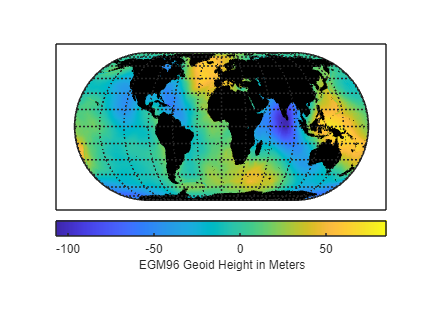

cb = colorbar('southoutside');
cb.Label.String = 'EGM96 Geoid Height in Meters';
geoshow('landareas.shp','FaceColor','black')

Get geoid heights and a geographic postings  reference object from the EGM96 geoid model. Then, display the geoid  heights as a surface using an Eckert projection.

[N,R] = egm96geoid;
figure
axesm eckert4
geoshow(N,R,'DisplayType','surface')

Add light and material. Then, view the map as a 3-D surface.

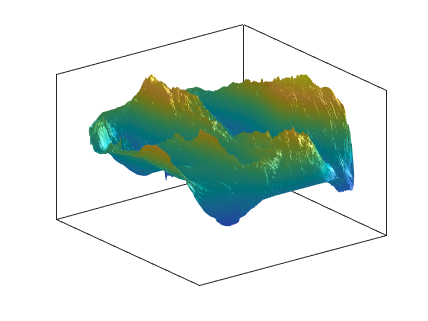

light
material(0.6*[1 1 1])
axis normal
view(3)

# Read and Display netCDF Files

This example shows how to load and plot data from netCDF files. MATLAB has multiple functions dedicated to handling data from netcdf sources. Documentation for these functions can be found [here](https://www.mathworks.com/help/matlab/network-common-data-form.html).

This example uses CRU_TS data from [***Climatic Research Unit (University of East Anglia) and Met Office***](https://www.uea.ac.uk/web/groups-and-centres/climatic-research-unit/data)*. *

ncdisp('cru_ts4.03.1901.1910.pre.dat.nc')

Source:
           C:\Users\lsammon\OneDrive - MathWorks\Documents\MATLAB\A_Demos\UMD Geosciences Demo\cru_ts4.03.1901.1910.pre.dat.nc
Format:
           classic
Global Attributes:
           Conventions = 'CF-1.4'
           title       = 'CRU TS4.03 Precipitation'
           institution = 'Data held at British Atmospheric Data Centre, RAL, UK.'
           source      = 'Run ID = 1905011326. Data generated from:pre.1905011321.dtb'
           history     = 'Thu  2 May 2019 06:31:34 BST : User ianharris : Program makegridsauto.for called by update.for'
           references  = 'Information on the data is available at http://badc.nerc.ac.uk/data/cru/'
           comment     = 'Access to these data is available to any registered CEDA user.'
           contact     = 'support@ceda.ac.uk'
Dimensions:
           lon  = 720
           lat  = 360
           time = 120   (UNLIMITED)
Variables:
    lon 
           Size:       720x1
           Dimensions: lon
           Datatype:   single
        

## Read and extract the required variables

Extract longtiude, latitude, and precipitation information. 

lon = double(ncread('cru_ts4.03.1901.1910.pre.dat.nc','lon'));
lat = double(ncread('cru_ts4.03.1901.1910.pre.dat.nc','lat'));
pre = ncread('cru_ts4.03.1901.1910.pre.dat.nc','pre');
time = ncread('cru_ts4.03.1901.1910.pre.dat.nc','time');


pre variable has a size of 720 x 360 x 120. Third channel corresponds to time. Extract precipitation information for a single day.

pre1 = pre(:,:,70);

## Visualization of historic rainfall

Create a mesh based on the available latitude and longitude data and plot the precipitation values on the grid.

latlowerlim = 37; latupperlim = 41;
latstepsize = 0.1;
lonlowerlim = -80; lonupperlim = -75;
lonstepsize = 0.1;


[newlat, newlon] = meshgrid(latlowerlim:latstepsize:latupperlim, ...
    lonlowerlim:lonstepsize:lonupperlim);

newpre = griddata(lat,lon,pre1,newlat,newlon);

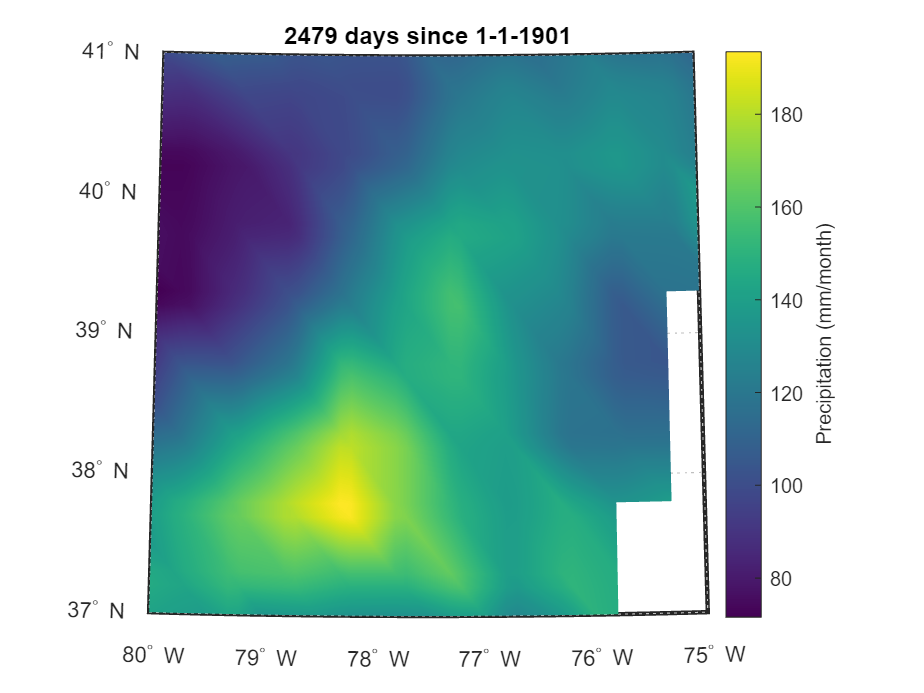

figure
ax2 = axesm('eqdconic'); % choose map projection
worldmap([latlowerlim latupperlim],[lonlowerlim lonupperlim])
geoshow(newlat,newlon,newpre,'DisplayType','surface')
title([num2str(time(70)) ' days since 1-1-1901'])

axis off; gridm on; framem on; 
cb = colorbar; % display colorbar
ylabel(cb,'Precipitation (mm/month)')

## Create figure animation with respect to time

Uncomment sections below if you want to see the animated view of how precipitation changes across region with different days.

This section may take longer duration to execute.

Example of how you can make this graphic look with changed colormap and adding **borders from File Exchange**. 

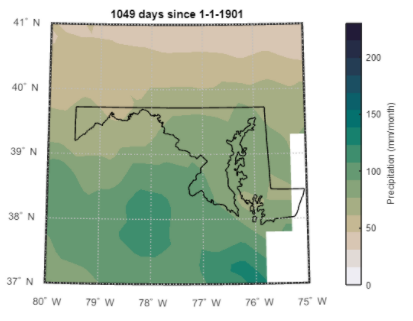

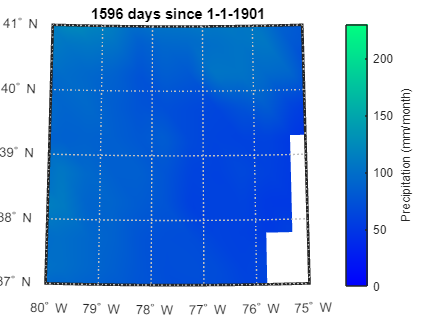

f = figure;
axesm('eqdconic')
    axis off; gridm on; framem on; 

    cb = colorbar; % display colorbar
    colormap(winter)
ylabel(cb,'Precipitation (mm/month)')
clim([0 230])


for i = 1:50
    pre1 = pre(:,:,i);
    
    newpre = griddata(lat,lon,pre1,newlat,newlon);
    title([num2str(time(i)) ' days since 1-1-1901']);

    worldmap([latlowerlim latupperlim],[lonlowerlim lonupperlim]);
    geoshow(newlat,newlon,newpre,'DisplayType','surface');
    hold on
    %bordersm('Maryland','-k') % function found on MATLAB File Exchange to
    % add state and country borders to maps.

    view([0 78])

    frame(i) = getframe(gcf);
end

figure
axes("Position",[0 0 1 1])
movie(frame)